## Problem 1

(a)(b)

clear;
% load data
y1 = [-0.4 0.58 0.089;
      -0.31 0.27 -0.04;
       0.38 0.055 -0.035;
      -0.15 0.53 0.011;
      -0.35 0.47 0.034;
       0.17 0.69 0.1;
      -0.011 0.55 -0.18;
      -0.27 0.61 0.12;
      -0.065 0.49 0.0012;
      -0.12 0.054 -0.063];
y2 = [0.83 1.6 -0.014;
      1.1 1.6 0.48;
     -0.44 -0.41 0.32;
      0.047 -0.45 1.4;
      0.28 0.35 3.1;
     -0.39 -0.48 0.11;
      0.34 -0.079 0.14;
     -0.3 -0.22 2.2;
      1.1 1.2 -0.46;
      0.18 -0.11 -0.49];
% find Sw & v
m_y1 = mean(y1); 
m_y2 = mean(y2);
Sw = zeros(3);
for i = 1:size(y1,1)
    Sw = Sw + (y1(i,:)'-m_y1')*(y1(i,:)'-m_y1')'/size(y1,1); 
    Sw = Sw + (y2(i,:)'-m_y2')*(y2(i,:)'-m_y2')'/size(y1,1);
end
v = inv(Sw)*(m_y1-m_y2)';
fprintf('v = %s, %s, %s',num2str(v(1)),num2str(v(2)),num2str(v(3)));

v = -3.8325, 2.1375, -0.76737

(c)

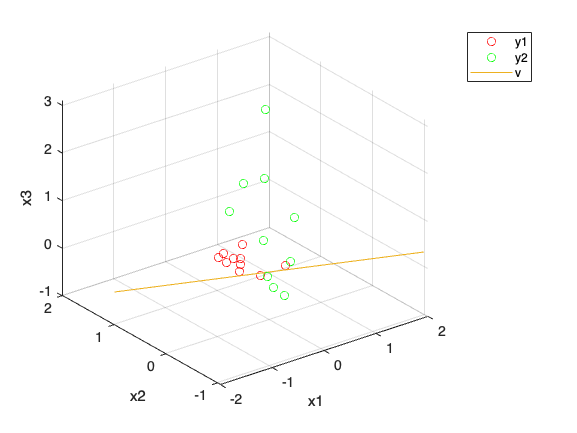

figure; 
scatter3(y1(:,1)',y1(:,2)',y1(:,3)','r'); 
hold on; 
scatter3(y2(:,1)',y2(:,2)',y2(:,3)','g'); 
t = linspace(-0.5,0.5); 
x = v(1)*t; 
y = v(2)*t; 
z = v(3)*t;
plot3(x,y,z); 
legend('y1','y2','v');
xlabel('x1');
ylabel('x2');
zlabel('x3');
hold off;

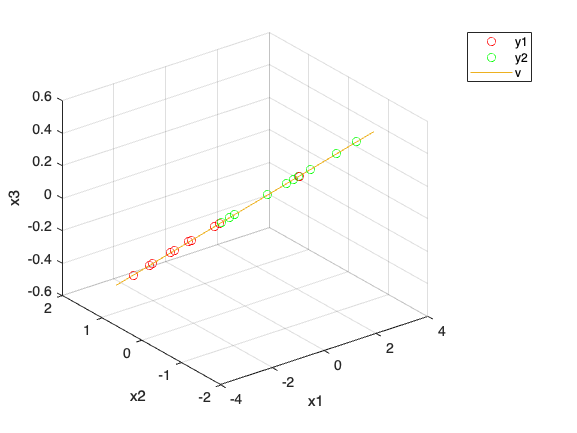

% project to v
figure;
for i = 1:size(y1,1)
    pc_y1(i) = (y1(i,:)*v)/norm(v);
    p_y1(:,i) = v.*pc_y1(i);
    pc_y2(i) = (y2(i,:)*v)/norm(v);
    p_y2(:,i) = v.*pc_y2(i);
end
scatter3(p_y1(1,:),p_y1(2,:),p_y1(3,:),'r'); 
hold on; 
scatter3(p_y2(1,:),p_y2(2,:),p_y2(3,:),'g'); 
t = linspace(-0.7,0.7); 
x = v(1)*t; y = v(2)*t; z = v(3)*t;
plot3(x,y,z); 
legend('y1','y2','v');
xlabel('x1');
ylabel('x2');
zlabel('x3');
hold off;

(d)

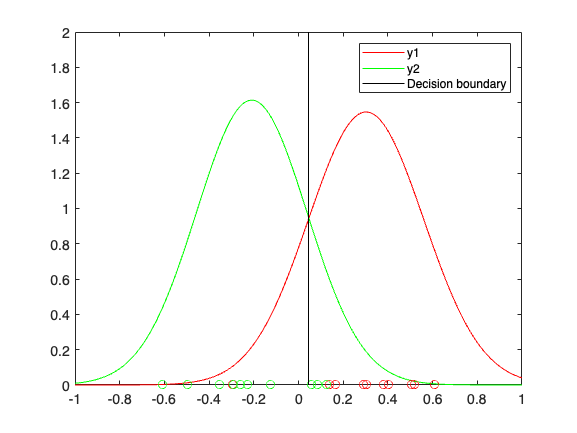

% fit distribution with a (univariate) Gaussian
pd1 = fitdist(pc_y1','Normal'); 
pd2 = fitdist(pc_y2','Normal');
t = linspace(-1,1,1000); 
pdf1 = pdf(pd1,t); 
pdf2 = pdf(pd2,t);
for i = 1:1000
    if pdf1(i)-pdf2(i) < 0.001
        limit = i;
    end
end
db=t(limit);
figure; 
hold on;
plot(t,pdf1,'r'); 
plot(t,pdf2,'g'); 
plot(linspace(-1,1,10),0,'k'); 
scatter(pc_y1,zeros(1,size(y1,1)),'r'); 
scatter(pc_y2,zeros(1,size(y1,1)),'g'); 
line([db,db],[0,2],'Color','k'); 
legend('y1','y2','Decision boundary');
box on;
hold off;

fprintf('Decision boundary =  %s',num2str(db));

Decision boundary =  0.045045

(e)

% calculate the training error
err = 0;
for i = 1:size(y1,1)
    if pc_y1(i) < t(limit)
        err = err + 1;
    end
end
for i = 1:size(y2,1)
    if pc_y2(i) > t(limit)
        err = err + 1;
    end
end
error = err/(size(y1,1)+size(y2,1));
fprintf('Training error =  %s', num2str(error));

Training error =  0.2

## Problem 2

(a) Perform PCA on the unlabeled points from the Fisher’ Iris flower data set '06HW1_iris.csv'.

(1) List the principal components explaining 95% of the total variance in the dataset.

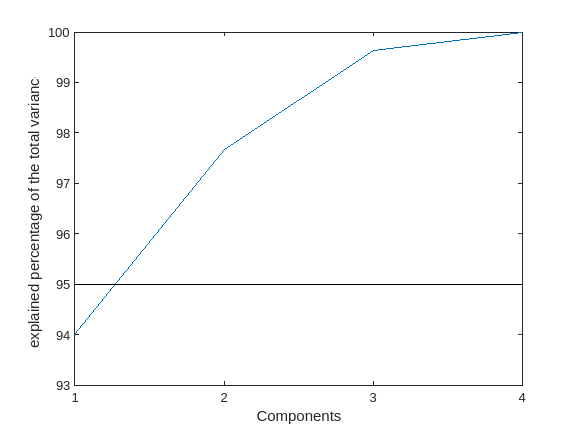

clear;
% load data
D = readtable('06HW1_iris.csv');
data=table2array(D(1:150,1:4));
data = normc(data);
[PC, var, expl] = pcacov(cov(data));
data_PCA = data*PC;
% calculate the explained percentage of the total variance
for i= 2:size(expl,1)
    expl(i)=expl(i)+expl(i-1);
end
var_total = sum(var);
figure;
plot(expl);xticks(1:4);
hold on;
y=[95 95 95 95]';
plot(y,'Color','k');
xlabel('Components');
ylabel('explained percentage of the total variance');
hold off;

(2) Plot the data points using the first two PCs as axes, distinguishing between the classes using different color or marker. 

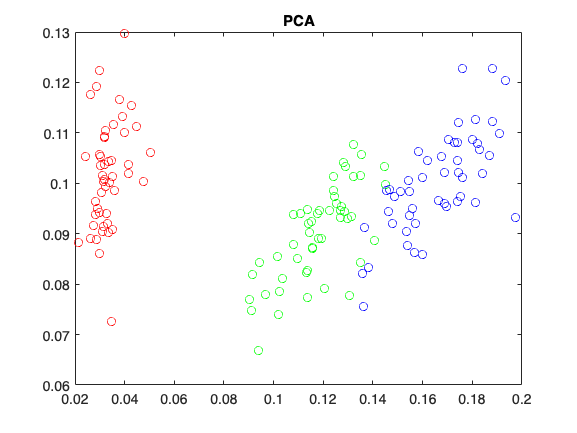

figure;
hold on;
scatter(data_PCA(1:50,1),data_PCA(1:50,2),'r');
scatter(data_PCA(51:100,1),data_PCA(51:100,2),'g'); 
scatter(data_PCA(101:150,1),data_PCA(101:150,2),'b');
title('PCA');
box on;
hold off;

(b) Perform LDA on the training set.

(1) Perform LDA on the original explanatory variables. The dataset should be normalized before performing the LDA. Plot the training and test sets using the first two linear discriminant axes. These can be on separate plots. Calculate the training and test errors. 

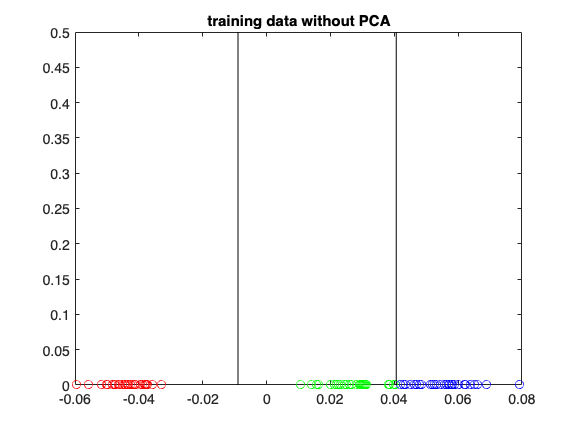

% LDA of orginal data
x_tr1=data(1:30,:);
x_tr2=data(51:80,:);
x_tr3=data(101:130,:);
x_te1=data(31:50,:);
x_te2=data(81:100,:);
x_te3=data(131:150,:);
x_train = [x_tr1;x_tr2;x_tr3];
x_test = [x_te1;x_te2;x_te3];
m_1 = mean(x_tr1); 
m_2 = mean(x_tr2); 
m_3 = mean(x_tr3);
m = (m_1+m_2+m_3)/3;

Sw = ((x_tr1-m_1)'*(x_tr1-m_1)+(x_tr2-m_2)'*(x_tr2-m_2)+(x_tr3-m_3)'*(x_tr3-m_3))/30;
Sb = ((m_1-m)'*(m_1-m)+(m_2-m)'*(m_2-m)+(m_3-m)'*(m_3-m))/3;
[V,~] = eig(inv(Sw)*Sb); 
v1 = V(:,1); 
p_1 = (x_train*v1)/norm(v1); 
p_2 = (x_test*v1)/norm(v1);
lim_train_a = (((m_1+m_2)/2)*v1)/norm(v1); 
lim_train_b = (((m_2+m_3)/2)*v1)/norm(v1);
m_1 = mean(x_te1); 
m_2 = mean(x_te2); 
m_3 = mean(x_te3);
lim_test_a = (((m_1+m_2)/2)*v1)/norm(v1); 
lim_test_b = (((m_2+m_3)/2)*v1)/norm(v1);

% calculate the training & test error
err_train = 0; 
err_test = 0;
for i = 1:30
    if p_1(i+60) < lim_train_b
        err_train = err_train + 1;
    end
    if (p_1(i+30) < lim_train_a) || (p_1(i+30) > lim_train_b)
        err_train = err_train + 1;
    end
    if p_1(i) > lim_train_a
        err_train = err_train + 1;
    end  
end
err_train = err_train/size(x_train,1); 
for i = 1:20
    if p_2(i+40) < lim_test_b
        err_test = err_test + 1;
    end
    if (p_2(i+20) < lim_test_a) || (p_2(i+20) > lim_test_b)
        err_test = err_test + 1;
    end
    if p_2(i) > lim_test_a
        err_test = err_test + 1;
    end  
end
err_test = err_test/size(x_test,1);
figure;
hold on; 
scatter(p_1(1:30),zeros(1,30),'r'); 
scatter(p_1(31:60),zeros(1,30),'g'); 
scatter(p_1(61:90),zeros(1,30),'b'); 
ylim([0,0.5]); 
title('training data without PCA'); 
box on;
line([lim_train_a,lim_train_a],[0,0.5],'Color','k'); 
line([lim_train_b,lim_train_b],[0,0.5],'Color','k');
hold off;

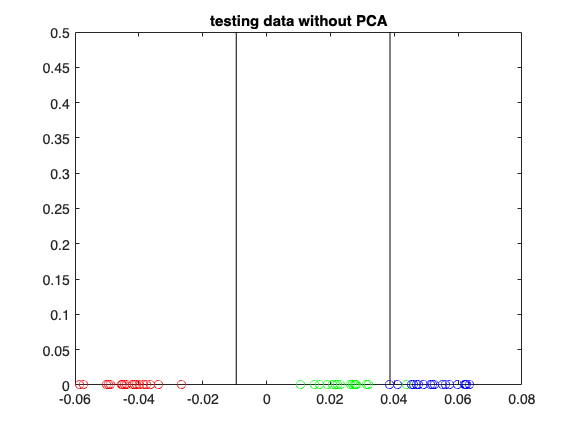

figure;
hold on; 
scatter(p_2(1:20),zeros(1,20),'r'); 
scatter(p_2(21:40),zeros(1,20),'g'); 
scatter(p_2(41:60),zeros(1,20),'b'); 
ylim([0,0.5]);
title('testing data without PCA');
box on;
line([lim_test_a,lim_test_a],[0,0.5],'Color','k'); 
line([lim_test_b,lim_test_b],[0,0.5],'Color','k');
hold off;

fprintf('Training error without PCA =  %s', num2str(err_train));

Training error without PCA =  0

fprintf('Testing error without PCA =  %s', num2str(err_test));

Testing error without PCA =  0.033333

(2) Perform LDA on the PCs obtained above. Plot the training and test set using the first two linear discriminant axes. These can be on separate plots. Calculate the training and test error.

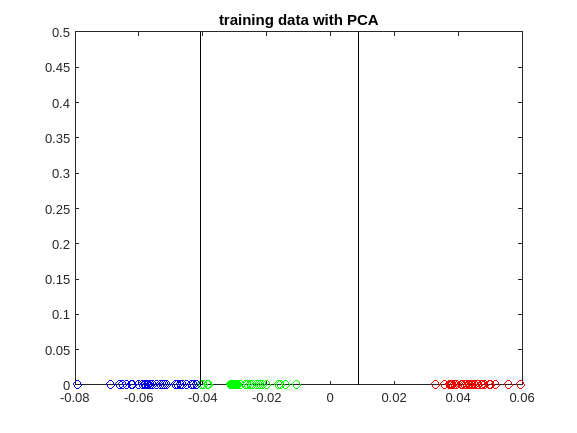

% LDA of PCA data
x_tr1=data_PCA(1:30,:);
x_tr2=data_PCA(51:80,:);
x_tr3=data_PCA(101:130,:);
x_te1=data_PCA(31:50,:);
x_te2=data_PCA(81:100,:);
x_te3=data_PCA(131:150,:);
x_train = [x_tr1;x_tr2;x_tr3];
x_test = [x_te1;x_te2;x_te3];
m_1 = mean(x_tr1); 
m_2 = mean(x_tr2); 
m_3 = mean(x_tr3);
m = (m_1+m_2+m_3)/3;

Sw = ((x_tr1-m_1)'*(x_tr1-m_1)+(x_tr2-m_2)'*(x_tr2-m_2)+(x_tr3-m_3)'*(x_tr3-m_3))/30;
Sb = ((m_1-m)'*(m_1-m)+(m_2-m)'*(m_2-m)+(m_3-m)'*(m_3-m))/3;
[V,D] = eig(inv(Sw)*Sb); 
v1 = V(:,1); 
v2 = V(:,2);
p_1 = (x_train*v1)/norm(v1); 
p_2 = (x_test*v1)/norm(v1);
lim_train_a = (((m_1+m_2)/2)*v1)/norm(v1); 
lim_train_b = (((m_2+m_3)/2)*v1)/norm(v1);
m_1 = mean(x_te1); 
m_2 = mean(x_te2); 
m_3 = mean(x_te3);
lim_test_a = (((m_1+m_2)/2)*v1)/norm(v1); 
lim_test_b = (((m_2+m_3)/2)*v1)/norm(v1);

% calculate the training & test error
err_train = 0; 
err_test = 0;
for i = 1:30
    if p_1(i+60) > lim_train_b
        err_train = err_train + 1;
    end
    if (p_1(i+30) > lim_train_a) || (p_1(i+30) < lim_train_b)
        err_train = err_train + 1;
    end
    
    if p_1(i) < lim_train_a
        err_train = err_train + 1;
    end
end
err_train = err_train/size(x_train,1);
for i = 1:20
    if p_2(i+40) > lim_test_b
        err_test = err_test + 1;
    end
    if (p_2(i+20) > lim_test_a) || (p_2(i+20) < lim_test_b)
        err_test = err_test + 1;
    end
    if p_2(i) < lim_test_a
        err_test = err_test + 1;
    end
end
err_test = err_test/size(x_test,1);
figure;
hold on; 
scatter(p_1(1:30),zeros(1,30),'r'); 
scatter(p_1(31:60),zeros(1,30),'g'); 
scatter(p_1(61:90),zeros(1,30),'b'); 
ylim([0,0.5]); 
title('training data with PCA');
box on;
line([lim_train_a,lim_train_a],[0,0.5],'Color','k'); 
line([lim_train_b,lim_train_b],[0,0.5],'Color','k');
hold off;

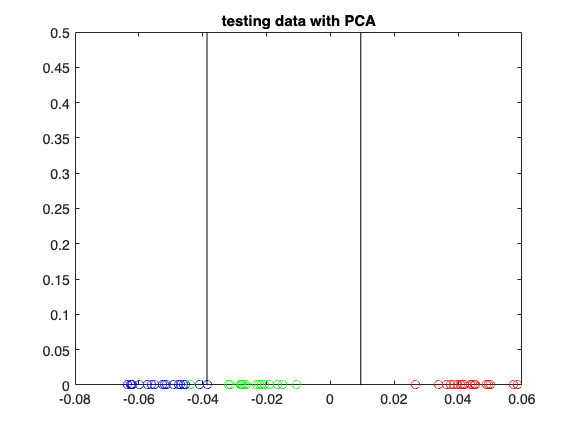

figure;
hold on; 
scatter(p_2(1:20),zeros(1,20),'r'); 
scatter(p_2(21:40),zeros(1,20),'g'); 
scatter(p_2(41:60),zeros(1,20),'b'); 
ylim([0,0.5]);
title('testing data with PCA'); 
box on;
line([lim_test_a,lim_test_a],[0,0.5],'Color','k'); 
line([lim_test_b,lim_test_b],[0,0.5],'Color','k');
hold off;

fprintf('Training error with PCA =  %s', num2str(err_train));

Training error with PCA =  0

fprintf('Testing error with PCA =  %s', num2str(err_test));

Testing error with PCA =  0.033333

(3)從以上結果可發現有無進行PCA，對此組資料的training或testing error都沒有太大影響，可見PCA在使用LDA時是多餘的處理。